%% ---------------------------------------------------------
% Load CSV files
% ----------------------------------------------------------
motion = readtable('C:/Users/dante/OneDrive/Documentos/UDEM/PEF/ExoRecordings/Recording 21-11-2025 15-15.csv');      % Contains: timestamp, M2Pos
emg    = readtable('C:/Users/dante/OneDrive/Documentos/UDEM/PEF/PEF - IMT 2da prueba/PEF_IMT209.csv');         % Contains: EMG2, EMG3, EMG4, EMG5


%% ---------------------------------------------------------
% Extract motion data
% ----------------------------------------------------------
t_mot  = motion.Var1;     % Motion timestamps (assumed in seconds)
M2Pos  = motion.Var9;

%% ---------------------------------------------------------
% Construct EMG timestamps (2000 Hz)
% ----------------------------------------------------------
dataEMG = emg{8:end,3:6}

dataEMG = 1.0e-03 *

   -0.0188   -0.0111   -0.0032   -0.0021
   -0.0188   -0.0119   -0.0046   -0.0012
   -0.0165   -0.0124   -0.0064   -0.0020
   -0.0114   -0.0117   -0.0066   -0.0026
   -0.0061   -0.0106   -0.0058   -0.0018
   -0.0024   -0.0104   -0.0054   -0.0012
   -0.0014   -0.0110   -0.0057   -0.0010
   -0.0021   -0.0122   -0.0056   -0.0017
   -0.0021   -0.0134   -0.0049   -0.0029
   -0.0013   -0.0127   -0.0040   -0.0037
   -0.0017   -0.0111   -0.0040   -0.0030
   -0.0035   -0.0095   -0.0054   -0.0017
   -0.0062   -0.0084   -0.0066   -0.0014
   -0.0080   -0.0086   -0.0071   -0.0023
   -0.0091   -0.0105   -0.0073   -0.0030


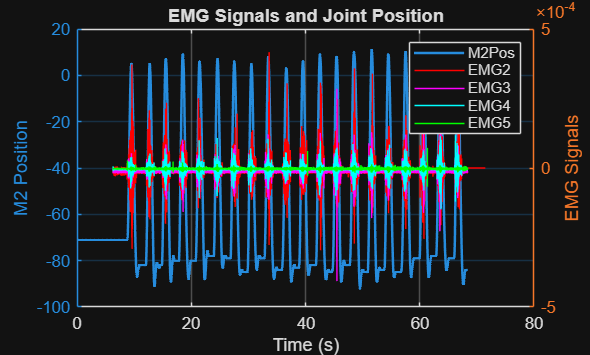

Fs = 2000;              % Sampling rate
N  = height(dataEMG);       % Number of EMG samples

t_emg = (0:N-1)' / Fs;  % EMG time vector (in seconds)

%% ---------------------------------------------------------
% Optional: Shift EMG time to align start of both signals
% (Assume both recordings start at same moment)
% If motion timestamp does NOT start at 0, shift EMG to match
% ----------------------------------------------------------
t_emg = t_emg +6.3;

%% ---------------------------------------------------------
% Plot both datasets
% ----------------------------------------------------------

figure;

%% Motion plot
%%subplot(2,1,1)
yyaxis left
plot(t_mot, M2Pos, 'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('M2 Position')
title('Motion Data')
grid on

%% EMG plot (all channels)

yyaxis right
plot(t_emg, dataEMG(:,1),'r-')
hold on
plot(t_emg, dataEMG(:,2),'m-')
plot(t_emg, dataEMG(:,3),'c-')
plot(t_emg, dataEMG(:,4),'g-')
hold off

xlabel('Time (s)')
ylabel('EMG Signals')
title('EMG Signals and Joint Position')
legend({'M2Pos','EMG2','EMG3','EMG4','EMG5'})
grid on